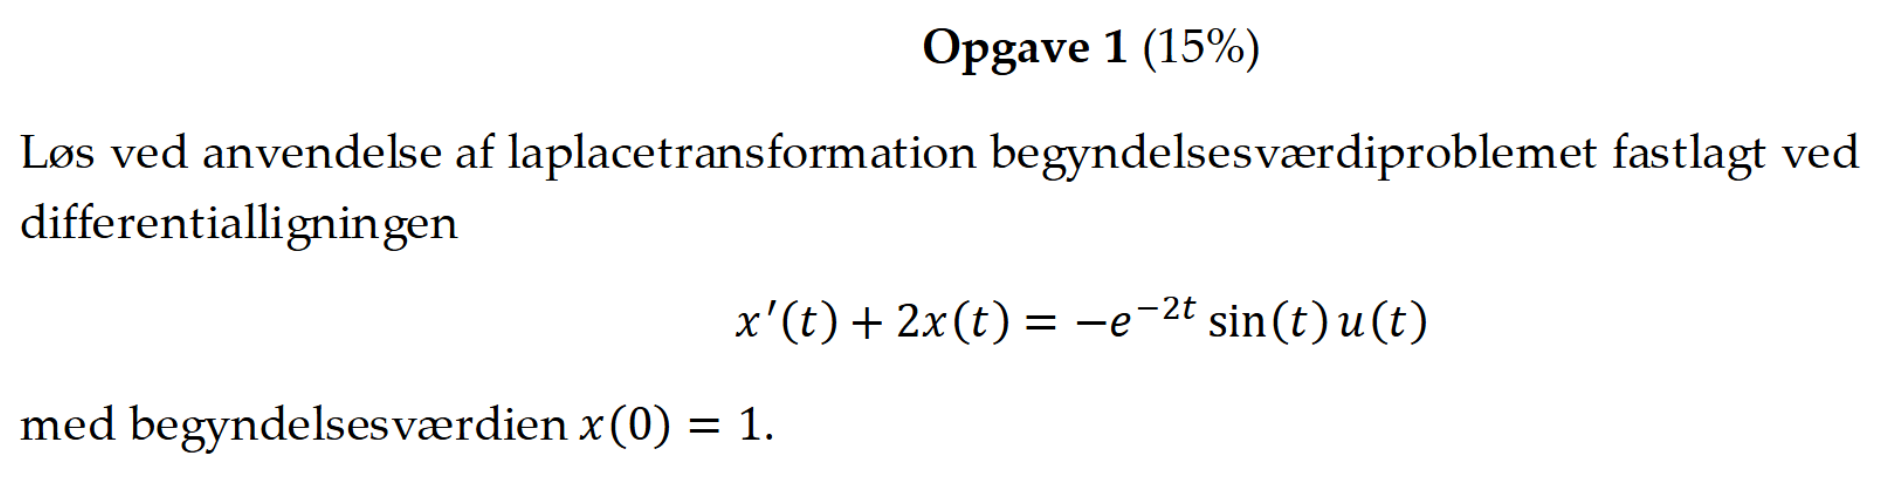

% Opsæt symbolske variable
syms t s;

% Definer differentialligningen: x'(t) + 2x(t) = -e^(-2t)*sin(t)*u(t)
% Differentialligning på standardform: a_n*y^(n) + ... + a_1*y' + a_0*y = f(t)
a = [1, 2];  % Koefficienter [a_1, a_0] for x'(t) + 2x(t)
b = [-1];    % Koefficient for højresiden

% Begyndelsesværdi
x0 = 1;      % x(0) = 1

% Højreside-funktion
f_t = exp(-2*t)*sin(t);

% Løs differentialligningen ved hjælp af biblioteket
[num, den] = ElektroMatBibTrinvis.diffLigningTilOverfoeringsfunktionMedForklaring(b, a);
[h_t, forklaringsOutput] = ElektroMatBibTrinvis.beregnUdgangssignalMedForklaring(tf(num, den), laplace(f_t, t, s), s, t);

% Tilføj begyndelsesværdien til den homogene løsning
x_t = h_t + x0*exp(-2*t);

disp('Løsningen på differentialligningen er:');
disp(x_t);

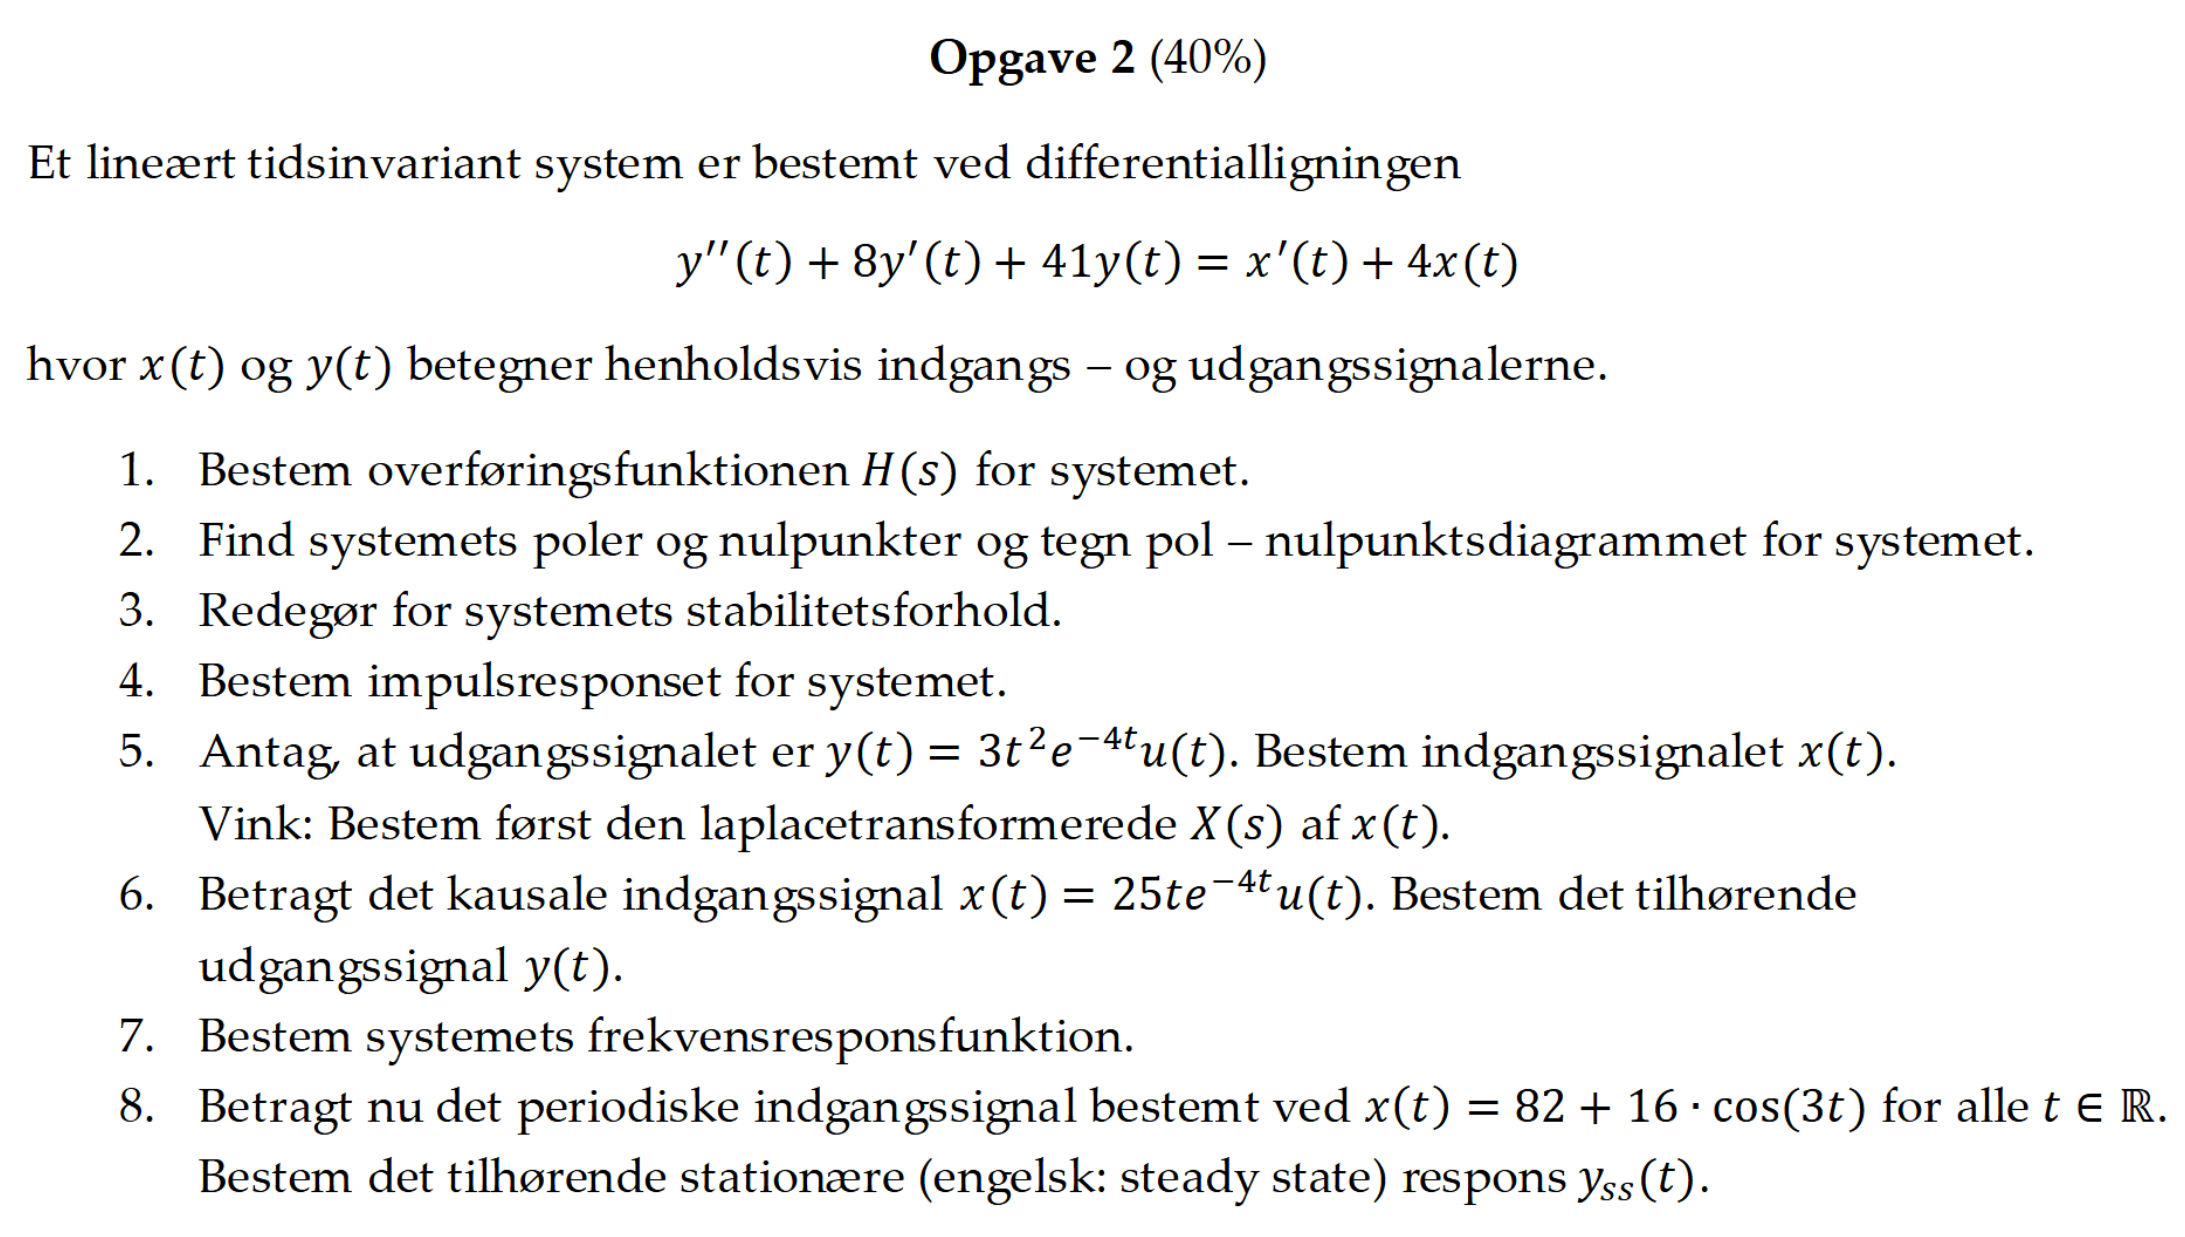

### 1. Bestem overføringsfunktionen 𝐻(𝑠) for systemet.

disp('Opgave 1: Bestem overføringsfunktionen 𝐻(𝑠) for systemet.');

Opgave 1: Bestem overføringsfunktionen 𝐻(𝑠) for systemet.



% Definerer koefficienterne for output og input
a = [1, 8, 41]; % Koefficienter for y'', y', y
b = [1, 4];     % Koefficienter for x', x

% Beregn overføringsfunktionen
[num, den, forklaring] = ElektroMatBibTrinvis.diffLigningTilOverfoeringsfunktionMedForklaring(b, a);

===== KONVERTERING AF DIFFERENTIALLIGNING TIL OVERFØRINGSFUNKTION =====
 
TRIN 1: Identificer differentialligningen
Vi starter med koefficienterne for differentialligningen.
   a = [1, 8, 41] (output koefficienter)\nb = [1, 4] (input koefficienter)
 
TRIN 2: Opskriv differentialligningen
Differentialligningen har følgende form:
   a_0 · y^(2) + a_1 · y^(1) + a_2 · y^(0) = b_0 · x^(1) + b_1 · x^(0)
 
TRIN 3: Tag Laplacetransformationen af begge sider
Vi anvender Laplacetransformationen på hele ligningen under antagelse af nulbetingelser.
   L{y^(n)} = s^n·Y(s) - s^(n-1)·y(0) - ... - y^(n-1)(0)
 
TRIN 4: Antag nulbetingelser
Vi antager at alle startbetingelser er nul: y(0) = y'(0) = ... = y^(n-1)(0) = 0.
   Dette giver: L{y^(n)} = s^n·Y(s)
 
TRIN 5: Opskriv ligningen i Laplace-domæne
Efter Laplacetransformation får vi:
   a_0 · s^2 · Y(s) + a_1 · s^1 · Y(s) + a_2 · s^0 · Y(s) = b_0 · s^1 · X(s) + b_1 · s^0 · X(s)
 
TRIN 6: Isolér overføringsfunktionen
Vi omskriver ligningen til at have Y


% Vis resultatet symbolsk
syms s;
H(s) = poly2sym(num, s) / poly2sym(den, s)

$$H(s) = \frac{s+4}{s^{2}+8\,s+41}$$

### 2. Find systemets poler og nulpunkter og tegn pol – nulpunktsdiagrammet for systemet

disp('Opgave 2: Find systemets poler og nulpunkter og tegn pol – nulpunktsdiagrammet for systemet');

Opgave 2: Find systemets poler og nulpunkter og tegn pol – nulpunktsdiagrammet for systemet



% Beregn poler og nuller
poler = roots(den);
nuller = roots(num);

% Vis poler og nuller
disp('Systemets poler:');

Systemets poler:


disp(poler);

  -4.0000 + 5.0000i
  -4.0000 - 5.0000i



disp('Systemets nuller:');

Systemets nuller:


disp(nuller);

    -4



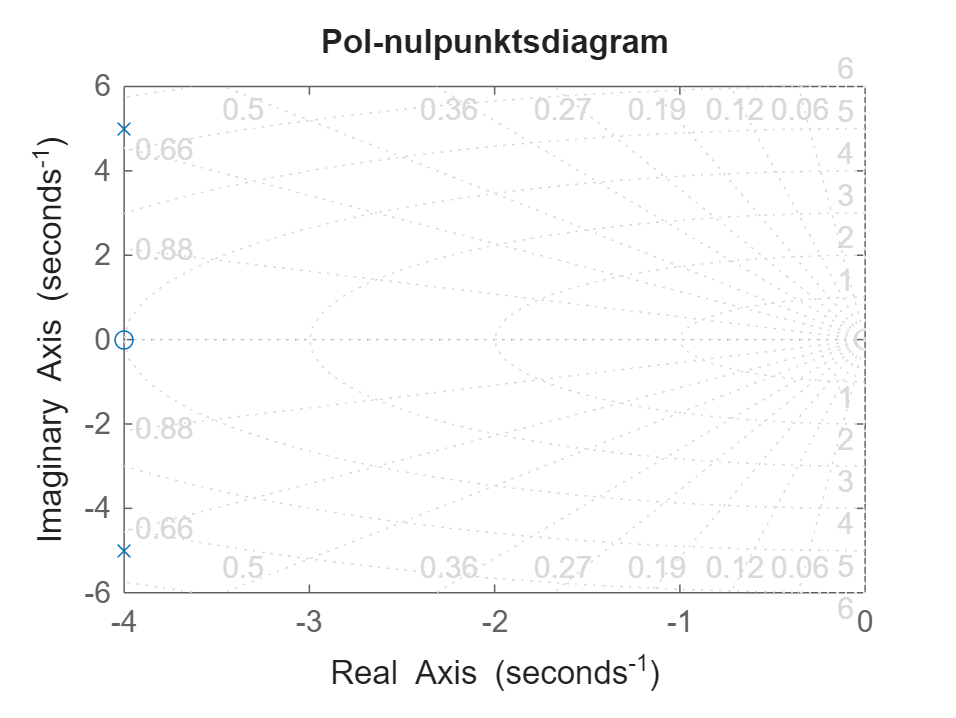


% Tegn pol-nulpunktsdiagram
figure;
pzmap(tf(num, den));
grid on;
title('Pol-nulpunktsdiagram');

### 3. Redegør for systemets stabilitetsforhold

disp('Opgave 3: Redegør for systemets stabilitetsforhold');

Opgave 3: Redegør for systemets stabilitetsforhold



% Analyser differentialligningen for at undersøge stabilitet
forklaringsOutput = ElektroMatBibTrinvis.analyserDifferentialligningMedForklaring(a);

===== ANALYSE AF DIFFERENTIALLIGNING =====
 
TRIN 1: Identificer differentialligningen
Vi starter med koefficienterne for differentialligningen.
   a = [1, 8, 41]
 
TRIN 2: Opskriv den homogene differentialligning
Den homogene differentialligning har følgende form:
   1 · y^(2) + 8 · y^(1) + 41 · y^(0) = 0
 
TRIN 3: Opskriv det karakteristiske polynomium
Det karakteristiske polynomium fås ved at erstatte y^(n) med λ^n.
   P(λ) = a_n·λ^n + a_(n-1)·λ^(n-1) + ... + a_1·λ + a_0
 
TRIN 4: Opskriv det karakteristiske polynomium
Det karakteristiske polynomium for denne differentialligning er:
   1 · λ^2 + 8 · λ^1 + 41 · λ^0 = 0
 
TRIN 5: Find rødderne i det karakteristiske polynomium
Rødderne bestemmer systemets opførsel.
   Rødderne i det karakteristiske polynomium er:\nλ_1 = -4.0000 + 5.0000i (kompleks)\nλ_2 = -4.0000 + -5.0000i (kompleks)
 
TRIN 6: Klassificér løsningstypen
For en andenordens ligning kan vi klassificere løsningstypen baseret på diskriminanten.
   Dette er en underdæmpet lø


% Tjek polers placering for at bestemme stabilitetstype
if any(real(poler) > 0)
    disp('Systemet er USTABILT da mindst én pol har positiv realdel.');
elseif any(abs(real(poler)) < 1e-10)  % Tjek for poler på den imaginære akse (med numerisk tolerance)
    disp('Systemet er MARGINALT STABILT da mindst én pol ligger på den imaginære akse.');
else
    disp('Systemet er ASYMPTOTISK STABILT da alle poler har negativ realdel.');
end

Systemet er ASYMPTOTISK STABILT da alle poler har negativ realdel.



% Vis polernes placering i det komplekse plan for detaljeret stabilitetsanalyse
disp('Poler:');

Poler:


for i = 1:length(poler)
    disp(['Pol ' num2str(i) ': ' num2str(poler(i))]);
end

Pol 1: -4+5i
Pol 2: -4-5i


### 4. Bestem impulsresponset for systemet.

disp('Opgave 4: Bestem impulsresponset for systemet.');

Opgave 4: Bestem impulsresponset for systemet.


===== BEREGNING AF STEPRESPONS =====
 
TRIN 1: Identificer overføringsfunktionen
Vi starter med at identificere systemets overføringsfunktion.
   H(s) = (s + 4)/(8*s + s^2 + 41)
 
TRIN 2: Definér stepfunktionen
Stepfunktionen (enhedsspring) er defineret som u(t), og dens Laplacetransformation er 1/s.
   L{u(t)} = 1/s
 
TRIN 3: Beregn systemresponsen på step-input
I Laplace-domænet er output = input × overføringsfunktion.
   Y(s) = H(s) · (1/s) = (s + 4)/(8*s + s^2 + 41) · (1/s)
 
TRIN 4: Anvend invers Laplacetransformation
For at finde tidsresponsen skal vi transformere tilbage til tidsdomænet.
   y(t) = L^(-1){Y(s)} = L^(-1){H(s) · (1/s)}
 
TRIN 4.5: Bemærk om kausalitet
Stepresponset er pr. definition kausalt og er kun defineret for t ≥ 0.
   g(t) = L^(-1){H(s)/s} · u(t)
 
TRIN 5: Analysér nøglekarakteristika
Vi kan beskrive systemets opførsel med følgende nøgletal:
   Stepresponsens nøglekarakteristika:\n\nSlutværdi: 0.0976\nStigetid (10% til 90%): 0.0922 sekunder\nMaksimal værdi: 0

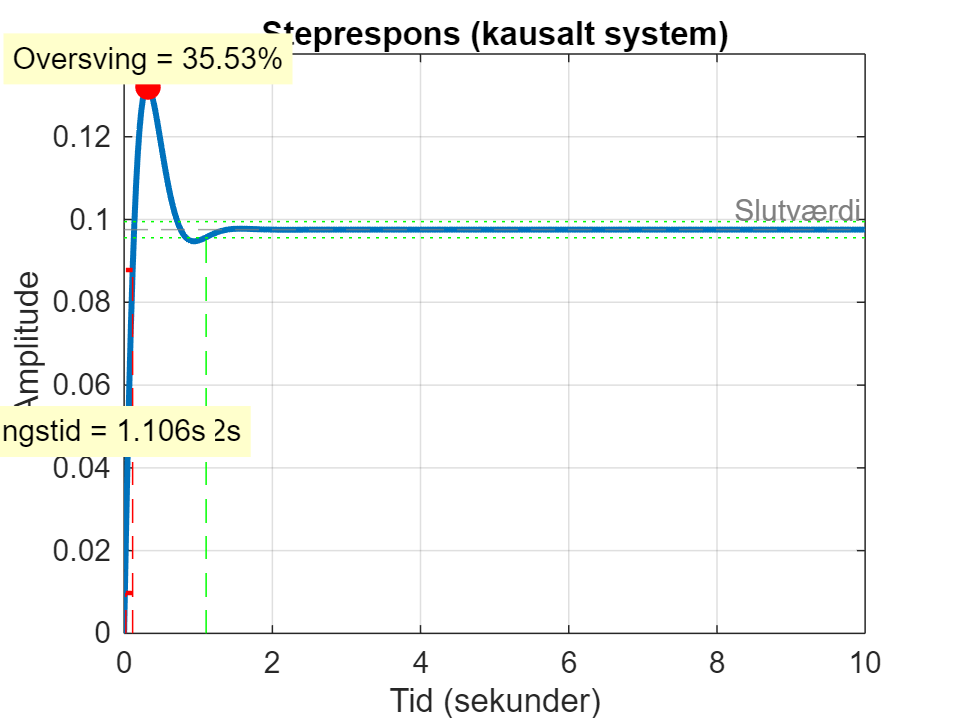


% Beregn systemets impulsrespons
[t, y, impulsForklaring] = ElektroMatBibTrinvis.beregnStepresponsMedForklaring(num, den, [0, 10]);


% Du kan også beregne impulsresponset ved invers Laplace-transformation af H(s)
syms s t;
H_s_sym = poly2sym(num, s) / poly2sym(den, s);
[h_t, invLapForklaring] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(H_s_sym, s, t);

===== INVERS LAPLACETRANSFORMATION =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med at identificere Laplace-transformationen, som skal konverteres tilbage til tidsdomænet.
   F(s) = (s + 4)/(8*s + s^2 + 41)
 
TRIN 2: Identificer funktionstypen som en brøk med kvadratisk nævner
Funktionen har en nævner på formen (s+a)²+b² med komplekse rødder.
   F(s) har nævneren (s+4)^2+5^2
 
TRIN 3: Undersøg tællerens form
Afhængigt af tællerens form får vi forskellige typer af inverse transformationer.
   For kvadratiske nævnere kan vi typisk få sinus- eller cosinusfunktioner.
 
TRIN 4: Genkend mønstret for dæmpet cosinus
Hvis F(s) = (s+a)/((s+a)²+b²), så er den inverse transformation en dæmpet cosinus.
   L^(-1){(s+a)/((s+a)^2+b^2)} = e^(-at)cos(bt)
 
TRIN 5: Formuler det endelige resultat
Den inverse Laplacetransformation er en dæmpet cosinusfunktion.
   f(t) = e^(-4t)cos(5t) for t ≥ 0
 
TRIN 6: Tilføj kausalitetsbetingelse
For LTI-systemer skal vi sikre at responset er 0 for t 

### 5. Antag, at udgangssignalet er $y\left(\textrm{𝑡}\right)=3{\textrm{𝑡}}^2 {\textrm{𝑒}}^{-4t} \textrm{𝑢}\left(\textrm{𝑡}\right)$. Bestem indgangssignalet $x\left(t\right)$. Vink: Bestem først den laplacetransformerede $X\left(S\right)$ af $x\left(t\right)$.

disp('Opgave 5: Antag, at udgangssignalet er . Bestem indgangssignalet . Vink: Bestem først den laplacetransformerede  af .');

Opgave 5: Antag, at udgangssignalet er . Bestem indgangssignalet . Vink: Bestem først den laplacetransformerede  af .



% Definér udgangssignalet
syms t s;
y_t = 3*t^2*exp(-4*t);

% Beregn Laplace-transformationen af y(t)
[Y_s, lapForklaring] = ElektroMatBibTrinvis.laplaceMedForklaring(y_t, t, s);

===== LAPLACETRANSFORMATION =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med at identificere den funktion, der skal transformeres.
   f(t) = 3*t^2*exp(-4*t)
 
TRIN 2: Beregn Laplacetransformationen symbolsk
Vi beregner integralet symbolsk:
   F(s) = 6/(s + 4)^3
 
RESULTAT:
   F(s) = 6/(s + 4)^3
 
===== AFSLUTTET: LAPLACETRANSFORMATION =====
 



% Find H(s) symbolsk
H_s_sym = poly2sym(num, s) / poly2sym(den, s);

% Beregn X(s) = Y(s)/H(s)
X_s = Y_s / H_s_sym;
X_s = simplify(X_s);

% Find x(t) ved invers Laplace-transformation
[x_t, invLapForklaring] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(X_s, s, t);

===== INVERS LAPLACETRANSFORMATION =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med at identificere Laplace-transformationen, som skal konverteres tilbage til tidsdomænet.
   F(s) = (6*(8*s + s^2 + 41))/(s + 4)^4
 
TRIN 2: Identificer funktionstypen som en rationel funktion
Funktionen er en rationel funktion, der kan opløses i partialbrøker.
   F(s) er en rationel funktion af s
 
TRIN 3: Brug partiel brøkopløsning
Vi opløser den rationelle funktion i en sum af simplere brøker.
   F(s) = A₁/(s-p₁) + A₂/(s-p₂) + ... + B₁/((s-q₁)²+r₁²) + ...
 
TRIN 4: Anvend invers transformation på hver delbrøk
Vi transformerer hver delbrøk separat ved hjælp af standardformler.
   L^(-1){1/(s-a)} = e^(at), L^(-1){b/((s+a)²+b²)} = e^(-at)sin(bt), ...
 
TRIN 5: Kombiner delresultater
Vi samler alle de inverse transformationer til den endelige løsning.
   f(t) = sum af alle inverse transformationer af delbrøker for t ≥ 0
 
TRIN 6: Tilføj kausalitetsbetingelse
For LTI-systemer skal vi sikr

### 6. Betragt det kausale indgangssignal $x\left(t\right)=25{\textrm{te}}^{-4t} u\left(t\right)$. Bestem det tilhørende udgangssignal $y\left(t\right)$.

### 7. Bestem systemets frekvensresponsfunktion.

### 8. Betragt nu det periodiske indgangssignal bestemt ved $x\left(t\right)=82+16*\cos \left(3t\right)$ for alle $\textrm{𝑡}\in \mathbb{R}$. Bestem det tilhørende stationære (engelsk: steady state) respons $y_{\textrm{ss}} \left(t\right)$.

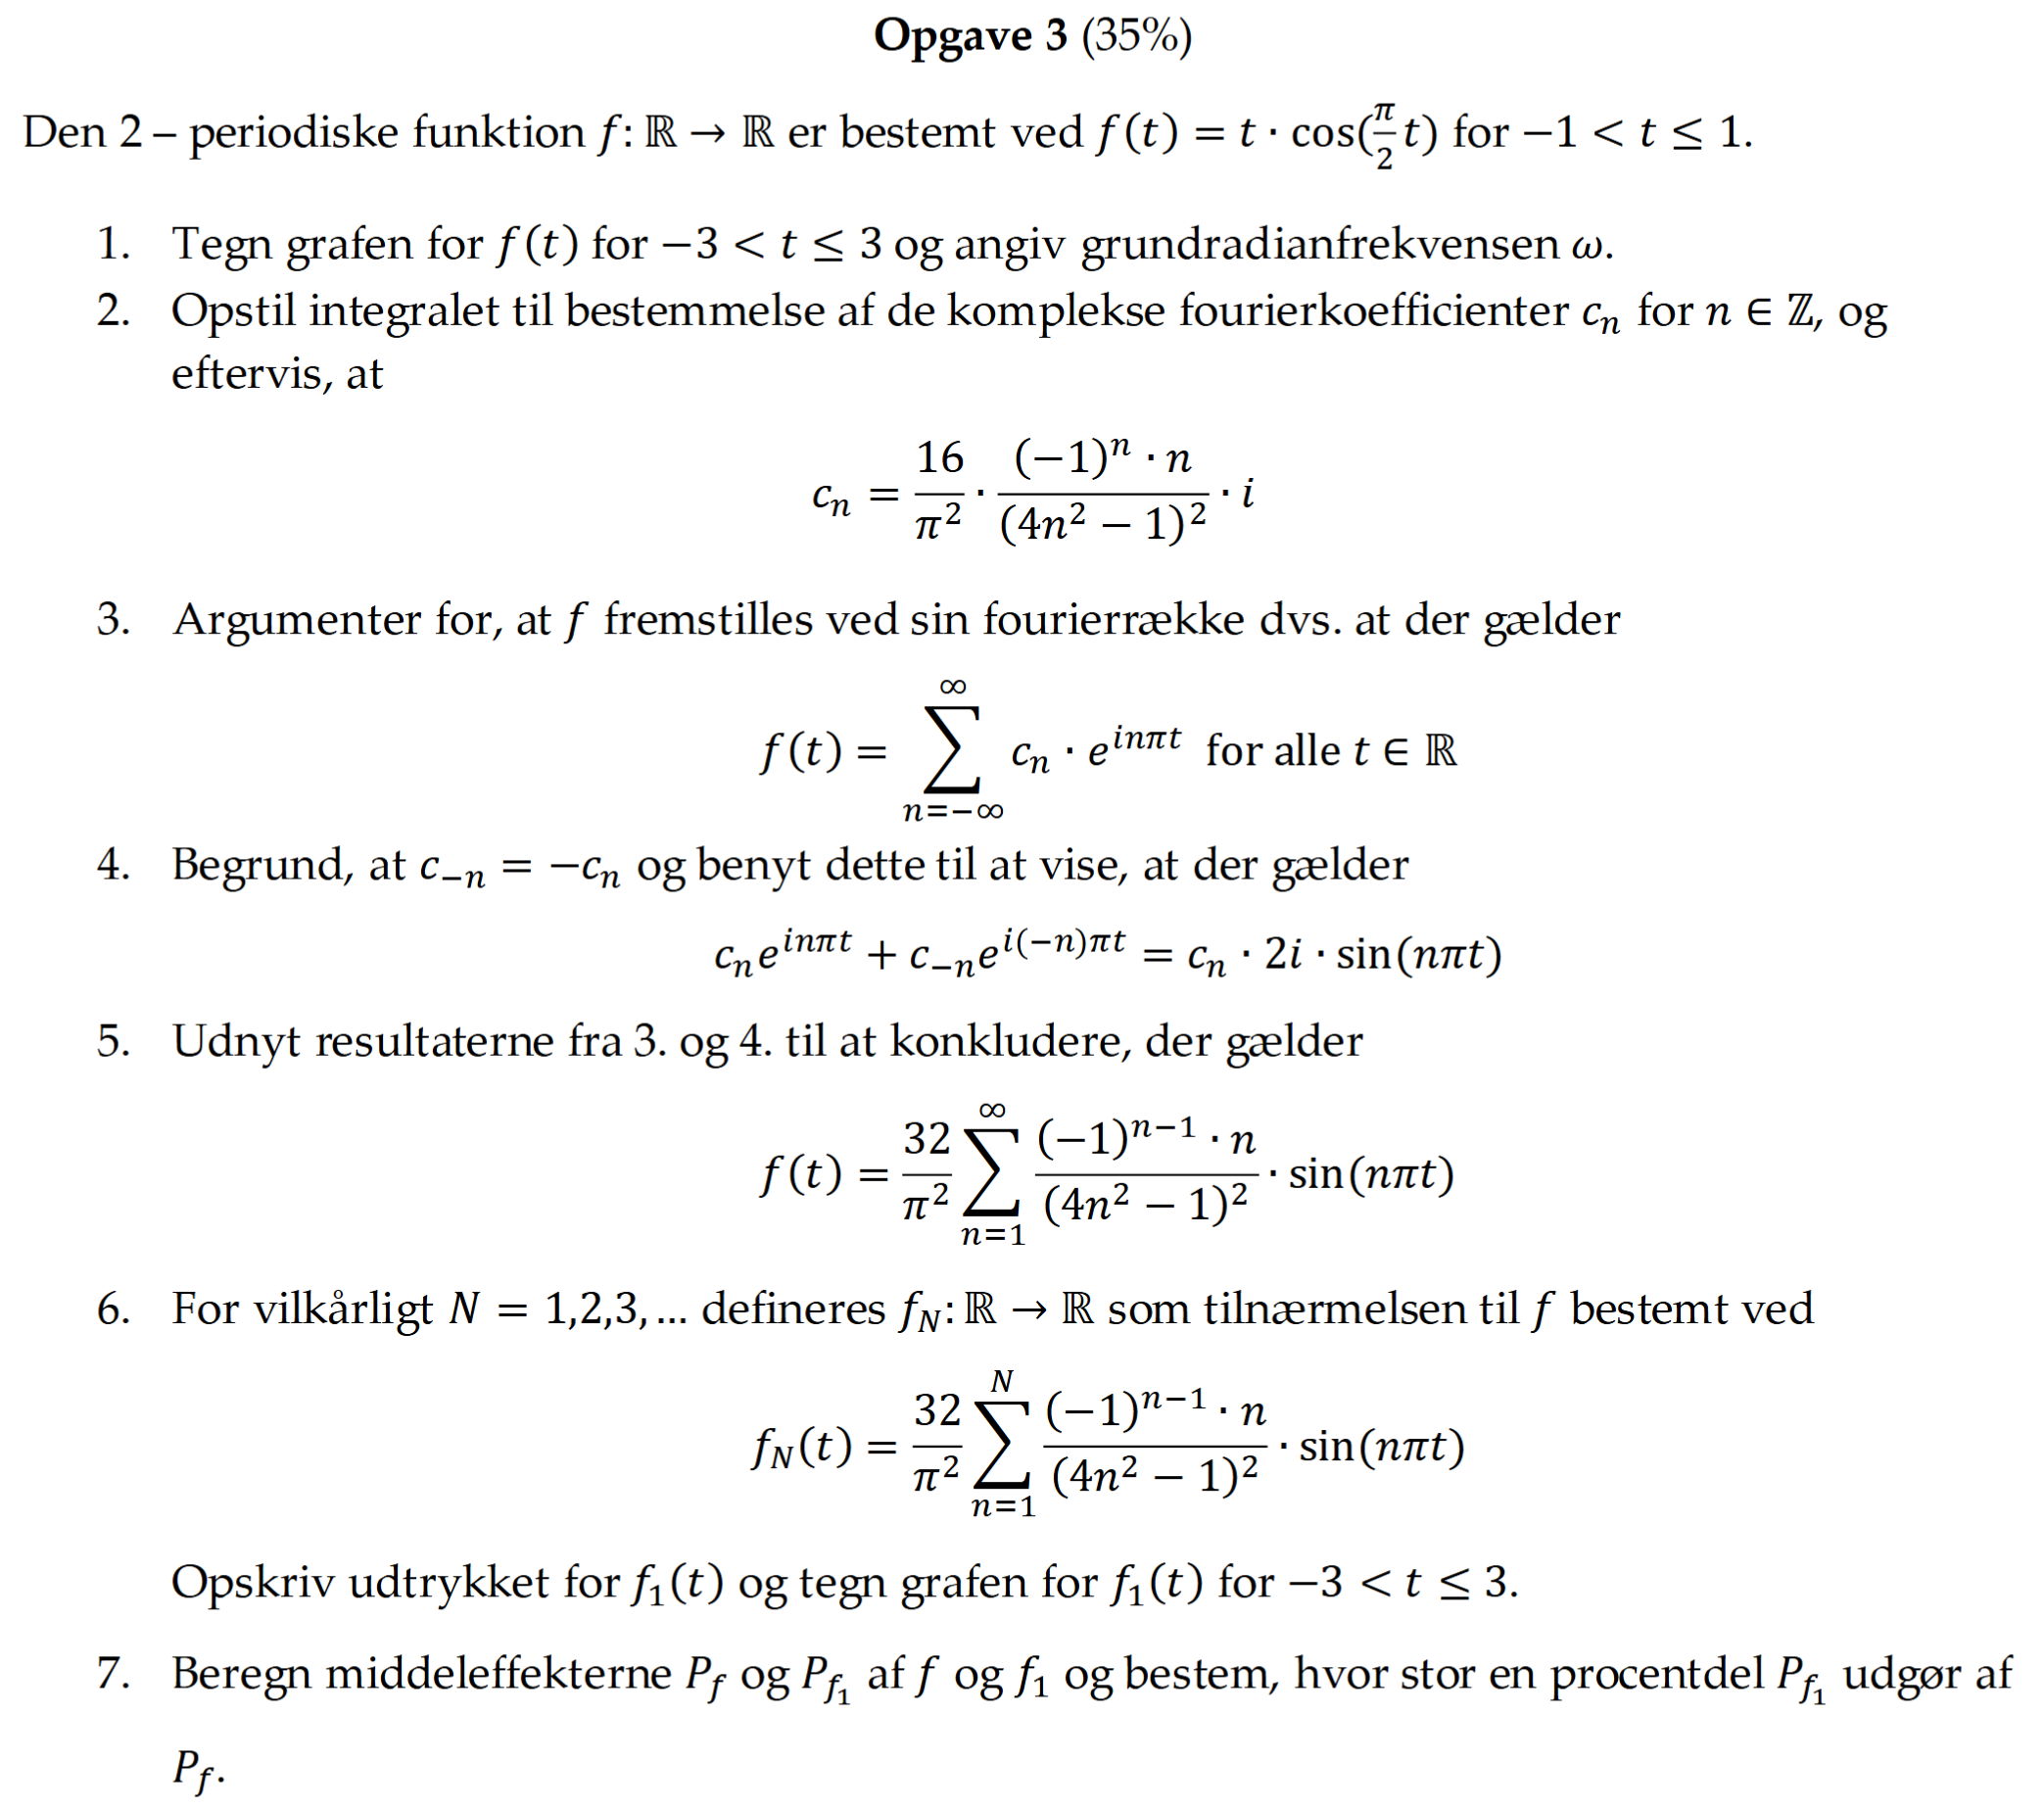

1. Tegn grafen for 𝑓(𝑡) for −3 < 𝑡 ≤ 3 og angiv grundradianfrekvensen 𝜔.

2. Opstil integralet til bestemmelse af de komplekse fourierkoefficienter 𝑐𝑛 for 𝑛 ∈ ℤ, og eftervis, at $c_n =\frac{16}{\pi^2 }=\frac{{\left(-1\right)}^n *n}{{\left(4n^2 -1\right)}^2 }*i$

3. Argumenter for, at 𝑓 fremstilles ved sin fourierrække dvs. at der gælder

4.